# Payload Software - RK4 Simulation and Dynamic Model of Guided Parachute

Colette Scott & Dan Pearson - 12/3/2023

clear variables; close all; clc;

## Global Constants

rho_inf = 1.22; % [kg/m^3] Air Density at sea level
C_d = 2.2; % [Non-Dimensional] **Guessed** Coefficient of Drag
R_air = 287; % [J/kg*K] Universal Gas Constant **Not used currently"
m = 21.77; % [kg] Total System Mass
g = 9.807; % [m/s]
W = m * g; % [N] System Weight - Force of Gravity on system
D_p = (3.65 * 2) / pi; % [m] Diameter of Parachute Profile
S_p = (pi/4)*(D_p^2); % [m^2] Surface area of parachute profile
l_cp = 2; % [m] Distance from x_cp to the center of mass

## System Dynamic Model

Dellicker, Scott, and Jim Bybee. “Low cost parachute guidance, navigation, and Control.” *15th Aerodynamic Decelerator Systems Technology Conference*, 1999, https://doi.org/10.2514/6.1999-1706. 

% Motion Equation
a_33 = (1/4)*rho_inf*(4/3)*pi*(D_p/2)^3; % Motion along Z-Axis
a_11 = (1/2)*a_33; % Motion along X-Axis
a_22 = (1/2)*a_33; % Motion along Y-Axis

a_44 = l_cp*D_p^2*a_11; % Motion about the X-Axis
a_55 = l_cp*D_p^2*a_11; % Motion about the Y-Axis

### State Space of Unguided System

$\vec{x} =\left\lbrack \begin{array}{c}
x\\
y\\
z\\
u\\
v\\
w
\end{array}\right\rbrack$,


$$\vec{\dot{x} } =\left\lbrack \begin{array}{c}
x_4 \\
x_5 \\
x_6 \\
\frac{-\frac{1}{2}\rho_{\infty } {\sqrt{x_4^2 +x_5^2 +x_6^2 }}^2 C_D *\cos \left(\gamma \right)\cos \left(\psi \right)}{\left(m+a_{11} \right)}\\
\frac{-\frac{1}{2}\rho_{\infty } {\sqrt{x_4^2 +x_5^2 +x_6^2 }}^2 C_D *\cos \left(\gamma \right)\sin \left(\psi \right)}{\left(m+a_{22} \right)}\\
\frac{-\frac{1}{2}\rho_{\infty } {\sqrt{x_4^2 +x_5^2 +x_6^2 }}^2 C_D *\sin \left(\gamma \right)+W}{\left(m+a_{33} \right)}
\end{array}\right\rbrack$$


where x is the position in the x-direction, y is the position in the y-direction, is the position in the z-direction, u is the velocity in the x-direction, v is the velocity in the y-direction & w is the velocity in the z-direction.

For this version, a constant flight path angle and heading will be chosen for the purpose of simple estimation.

fpa = deg2rad(90); % [deg] Flight Path Angle
hdg = deg2rad(0); % [deg] Heading Angle

x_dot_unguided = @(x,u) [
    x(4);
    x(5);
    x(6);
    ((0.5*rho_inf*(sqrt(x(4)^2+x(5)^2+x(6)^2)*C_d)^2*cos(fpa)*cos(hdg)) / (m+a_11));
    ((0.5*rho_inf*(sqrt(x(4)^2+x(5)^2+x(6)^2)*C_d)^2*cos(fpa)*sin(hdg)) / (m+a_22));
    ((0.5*rho_inf*sqrt(x(4)^2+x(5)^2+x(6)^2)*C_d)^2*sin(fpa) - W) / (m+a_33);
];

% x_dot_unguided = @(x,u) [
%     m+a_11 0 0;
%     0 m+a_22 0;
%     0 0 m+a_33;
%     ]^(-1) * (((1/2)*rho_inf*sqrt(x(1)^2+x(2)^2+x(3)^2))*C_d*S_p/(sqrt(x(1)^2+x(2)^2+x(3)^2)) * [x(1); x(2); x(3)] + [0;0;W]);

## RK4 Propagation

dt = 0.025;
t_0 = 0;
t = t_0;
t_f = 300;
timeSlice = t_0:dt:t_f;
numTimePts = t_f / dt+1;
tRecord = zeros(1,numTimePts);  
tRecord(1,1) = t;

### Intialize RK4

The system can be initialized with a position of 335m (~1100ft) and a negligible velocity.  The flight path angle and heading can be assumed to be a constant of 0 through the duration of the simulation.  For the future, this assumption would not be accurate and incorporating rotation into the model will greatly affect the results.

%      x, y, z, u, v, w
x_t = [0; 0; 322.6100; 0; 0; 0];

% Create a log array for the RK4 Results
xRecord = zeros(length(x_t), numTimePts);
xRecord(:,1) = x_t; % Input initial state vector

colNum = 1;
while(t < t_f)
    colNum = colNum + 1;
    t = t+dt;

    k1 = dt*x_dot_unguided(x_t);
    k2 = dt*x_dot_unguided(x_t+(1/2)*k1);
    k3 = dt*x_dot_unguided(x_t+(1/2)*k2);
    k4 = dt*x_dot_unguided(x_t+k3);

    x_t = x_t + (1/6)*k1 + (1/3)*k2 + (1/3)*k3 + (1/6)*k4;

    v = [x_t(4);x_t(5);x_t(6)];

    xRecord(:, colNum) = x_t;
    tRecord(1, colNum) = t;
end

### Load Polaris Data

% csvLog = readtable('PolarisData.csv');

## Results

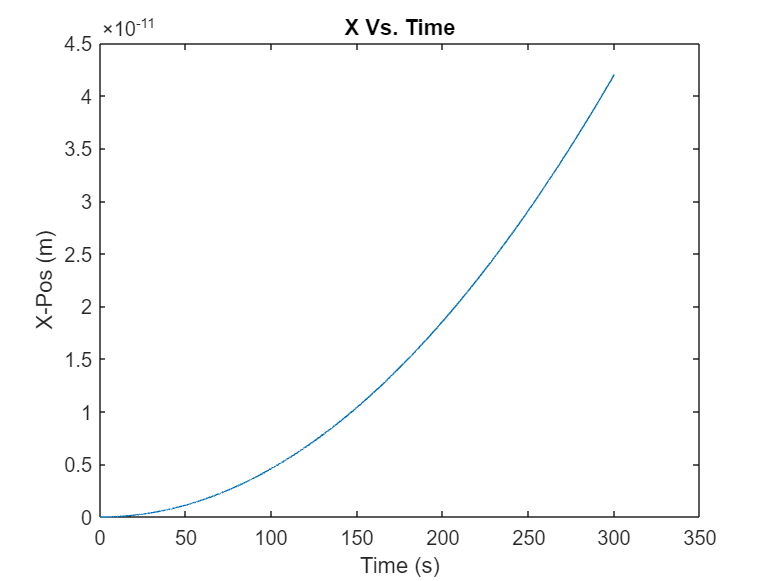

figure();
plot(tRecord, xRecord(1,:)); % X-Position vs Time
title("X Vs. Time");
xlabel("Time (s)");
ylabel("X-Pos (m)");

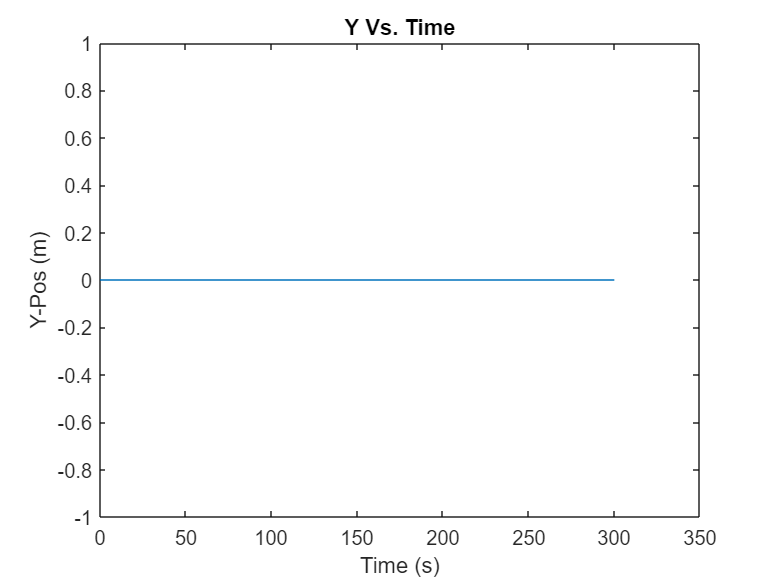


figure();
plot(tRecord, xRecord(2,:)); % Y-Position vs Time
title("Y Vs. Time");
xlabel("Time (s)");
ylabel("Y-Pos (m)");

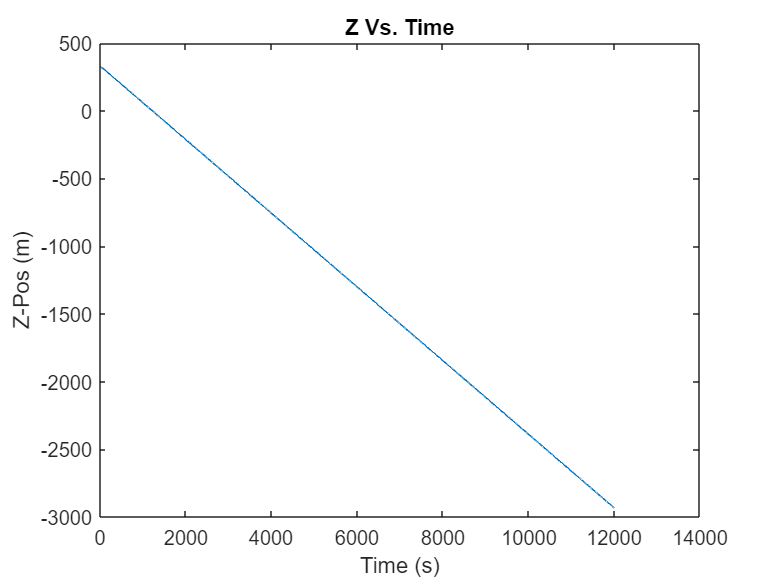


figure();
% plot(tRecord, xRecord(3,:)); % Z-Position vs Time
plot(xRecord(3,:))
hold on;
% plot(csvLog.altitude(7722:8210));
title("Z Vs. Time");
xlabel("Time (s)");
ylabel("Z-Pos (m)");

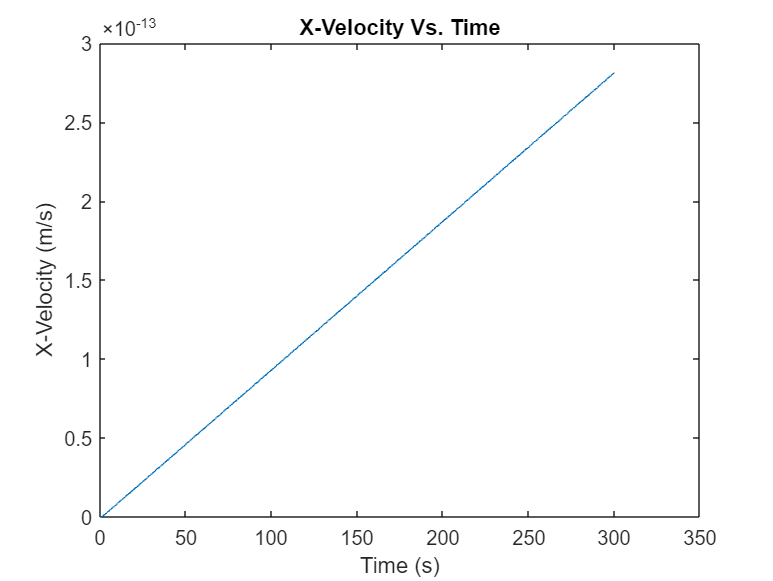


figure();
plot(tRecord, xRecord(4,:)); % X-Velocity vs Time
title("X-Velocity Vs. Time");
xlabel("Time (s)");
ylabel("X-Velocity (m/s)");

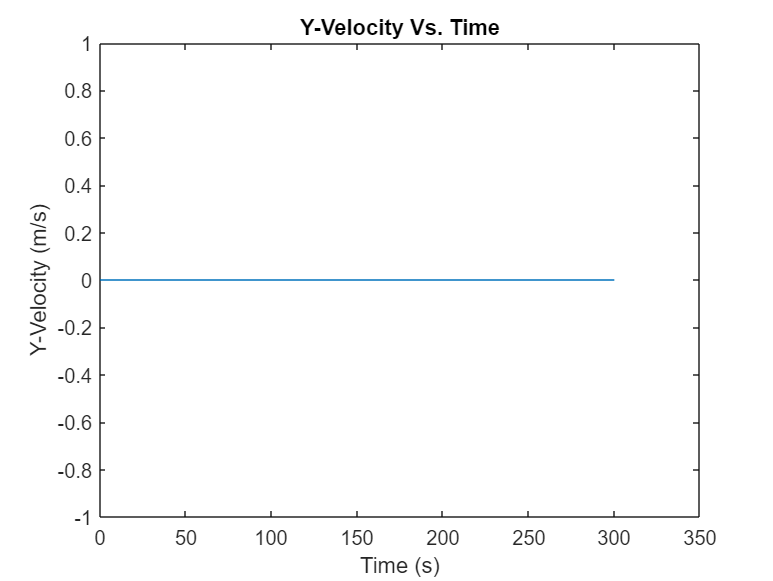


figure();
plot(tRecord, xRecord(5,:)); % Y-Velocity vs Time
title("Y-Velocity Vs. Time");
xlabel("Time (s)");
ylabel("Y-Velocity (m/s)");

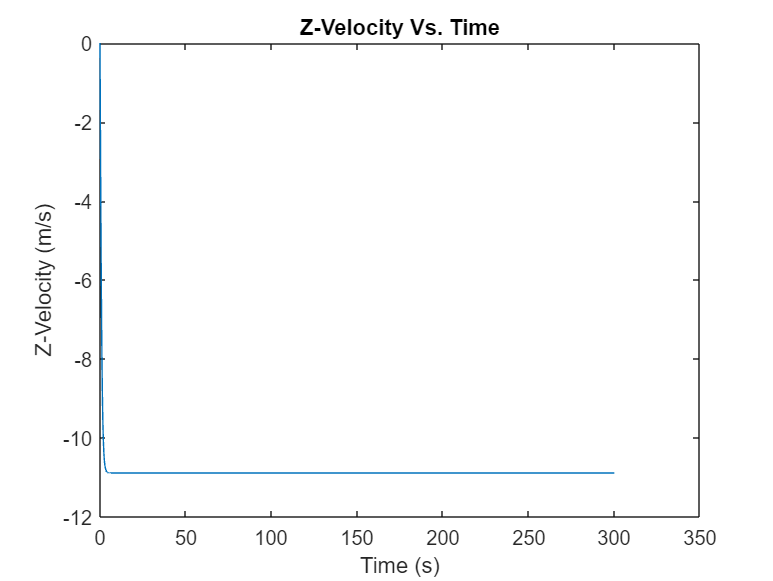


figure();
plot(tRecord, xRecord(6,:)); % Z-Velocity vs Time
title("Z-Velocity Vs. Time");
xlabel("Time (s)");
ylabel("Z-Velocity (m/s)");

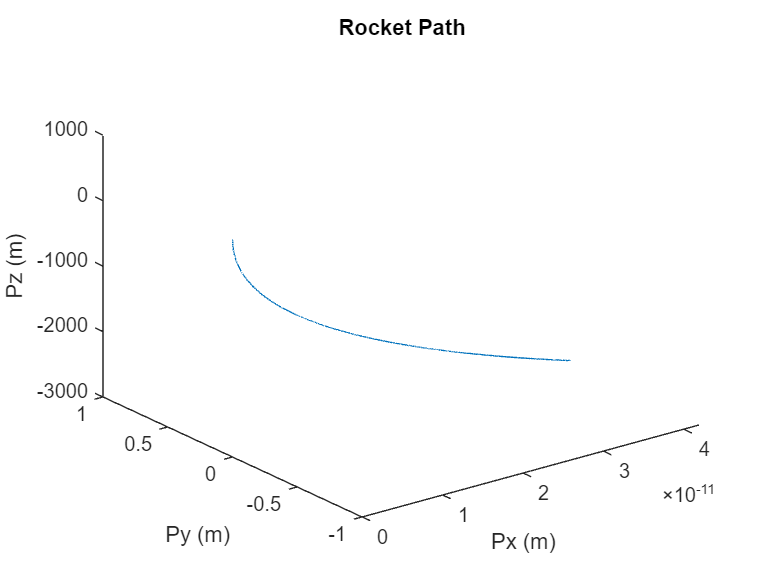


figure();
plot3(xRecord(1,:), xRecord(2,:), xRecord(3,:));
title("Rocket Path");
xlabel("Px (m)");
ylabel("Py (m)");
zlabel("Pz (m)");
hold on;